# Splot dwóch sygnałów dyskretnych

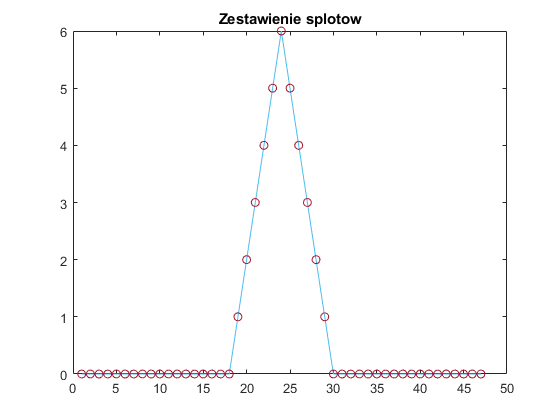

clear all

x = [zeros(1,9) ones(1,6) zeros(1,9)];
h = x;

conv_my = myconv(x,h);
conv_matlab = conv(x,h);

figure(1)
title("Zestawienie splotow")
plot(1:length(conv_my), conv_my)
hold on
scatter(1:length(conv_my), conv_matlab)

na podstawie

http://www.songho.ca/dsp/convolution/convolution.html

moje implementacje:

function Y = myconv(x, h)
    n = length(x);
    m = length(h);
    
    X=[x,zeros(1,n)];
    H=[h,zeros(1,m)];
    
    for i=1:n+m-1 % for every sample (0:suma)
        Y(i)=0;
        for k=1:m % for each element in h
            if(i-k+1>0)
                Y(i)=Y(i)+X(k)*H(i-k+1);
            else
            end
        end
    end
end